# Modelo robot movil

## Constantes

syms a b theta xp yp tp r t 

%medidas
a = 11.78/2;
b = 9.13/2;
r = 1.19;
%Tiempo en el que se llegara al lugar [s]
T = 10;
%Posiciones en cm
xi = 0;%x inicial
yi = 0;%y inicial
xf = 100;%x final
yf = 100;%y final
d = sqrt((xf-xi)^2+(yf-yi)^2);
v = d/T;%cm/s
psi = atan2(yf-yi,xf-xi);
%Angulos en rad
ti = 0;%theta inicial
tf = pi;%theta final

%velocidades del robot
xp = v*sin(psi);
yp = v*cos(psi);
tp = pi/T;%rad/s


theta = tp*t %El angulo dependera del tiempo

$$theta = \frac{\pi \,t}{10}$$


RZ = [cos(theta),-sin(theta),0;sin(theta),cos(theta),0;0,0,1]

$$RZ = \left(\begin{array}{ccc} \cos\left(\frac{\pi \,t}{10}\right) & -\sin\left(\frac{\pi \,t}{10}\right) & 0\\ \sin\left(\frac{\pi \,t}{10}\right) & \cos\left(\frac{\pi \,t}{10}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

EI = [xp;yp;tp]

EI =    10.0000
   10.0000
    0.3142


ER = RZ^(-1)*EI

$$ER = \begin{array}{l} \left(\begin{array}{c} \sigma_{1}+\sigma_{2}\\ \sigma_{1}-\sigma_{2}\\ \frac{\pi }{10} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{10\,\cos\left(\frac{\pi \,t}{10}\right)}{{\cos\left(\frac{\pi \,t}{10}\right)}^{2}+{\sin\left(\frac{\pi \,t}{10}\right)}^{2}}\\ \sigma_{2}=\frac{10\,\sin\left(\frac{\pi \,t}{10}\right)}{{\cos\left(\frac{\pi \,t}{10}\right)}^{2}+{\sin\left(\frac{\pi \,t}{10}\right)}^{2}} \end{array}$$

%set L
L = sqrt(a*a+b*b)

L = 7.4519

%Set alphas
alpha1 = atan(b/a)

alpha1 = 0.6593

alpha2 = pi-alpha1

alpha2 = 2.4823

alpha3 = pi+alpha1

alpha3 = 3.8009

alpha4 = 2*pi-alpha1

alpha4 = 5.6238

alpha = [alpha1;alpha2;alpha3;alpha4]

alpha =     0.6593
    2.4823
    3.8009
    5.6238


%Set betas
%90 - alpha + angulodeU1
beta1 = pi/2-alpha1

beta1 = 0.9115

beta2 = pi/2-alpha2 

beta2 = -0.9115

beta3 = pi/2-alpha3

beta3 = -2.2301

beta4 = pi/2-alpha4

beta4 = -4.0531

beta = [beta1;beta2;beta3;beta4]

beta =     0.9115
   -0.9115
   -2.2301
   -4.0531


J = [sin(alpha+beta),-cos(alpha+beta),-L*cos(beta)]

J =     1.0000   -0.0000   -4.5650
    1.0000   -0.0000   -4.5650
    1.0000   -0.0000    4.5650
    1.0000   -0.0000    4.5650


J(abs(J)<1e-3)=0;
% C=[cos(alpha+beta), sin(alpha+beta), L*sin(beta)]
J2 = r*eye(4)

J2 =     1.1900         0         0         0
         0    1.1900         0         0
         0         0    1.1900         0
         0         0         0    1.1900



% A = [J(1,:);J(3,:)]
% phi = sym('phi',[2,1])
% eq = vpa(A*ER == [phi],3)
% [phi_1,phi_2] = solve(eq,[transpose(phi)])
phip = J2^(-1)*J*ER;
phip = vpa(simplify(phip),3)

$$phip = \left(\begin{array}{c} 11.9\,\sin\left(0.314\,t+0.785\right)-1.21\\ 11.9\,\sin\left(0.314\,t+0.785\right)-1.21\\ 11.9\,\sin\left(0.314\,t+0.785\right)+1.21\\ 11.9\,\sin\left(0.314\,t+0.785\right)+1.21 \end{array}\right)$$

syms t
VR = vpa(sum(phip*r)/4,3)

$$VR = 14.1\,\sin\left(0.314\,t+0.785\right)$$


X = vpa(VR*t*cos(theta),3)

$$X = 14.1\,t\,\sin\left(0.314\,t+0.785\right)\,\cos\left(0.314\,t\right)$$

Y = vpa(VR*t*sin(theta),3)

$$Y = 14.1\,t\,\sin\left(0.314\,t+0.785\right)\,\sin\left(0.314\,t\right)$$

t = 0:0.1:T

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


X = eval(X)

X =          0    1.0269    2.1103    3.2436    4.4198    5.6315    6.8710    8.1304    9.4015   10.6760   11.9455   13.2015   14.4354   15.6388   16.8033   17.9209   18.9836   19.9836   20.9136   21.7666   22.5360   23.2159   23.8005   24.2848   24.6644   24.9354   25.0948   25.1400   25.0693   24.8816   24.5768   24.1551   23.6180   22.9674   22.2061   21.3378   20.3667   19.2980   18.1374   16.8916   15.5676   14.1734   12.7175   11.2090    9.6574    8.0730    6.4662    4.8480    3.2298    1.6231


Y = eval(Y)

Y =          0    0.0323    0.1327    0.3065    0.5581    0.8915    1.3100    1.8164    2.4126    3.1000    3.8792    4.7502    5.7122    6.7637    7.9025    9.1258   10.4300   11.8109   13.2637   14.7829   16.3624   17.9956   19.6754   21.3941   23.1436   24.9156   26.7011   28.4910   30.2761   32.0467   33.7930   35.5055   37.1741   38.7892   40.3411   41.8201   43.2172   44.5230   45.7290   46.8268   47.8085   48.6666   49.3944   49.9854   50.4341   50.7354   50.8852   50.8799   50.7168   50.3940


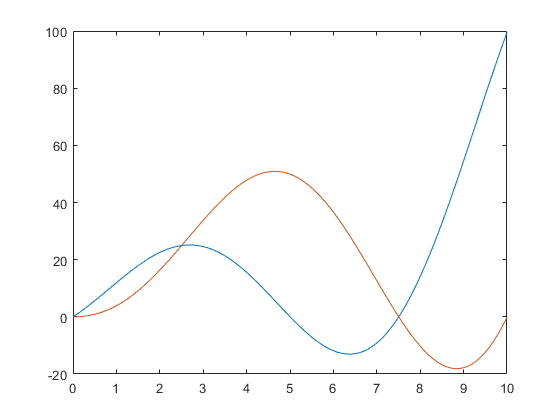

plot(t,X)
hold on
plot(t,Y)
hold off

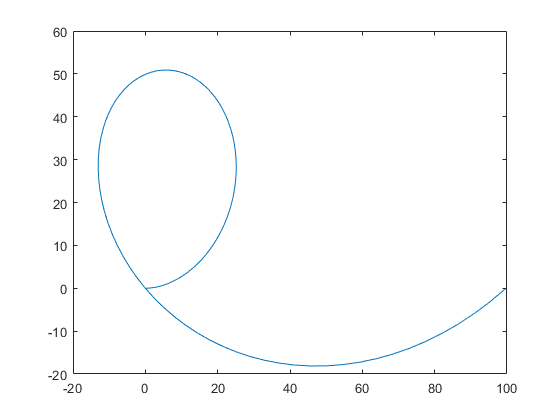

plot(X,Y)

% EI2 = EI*t;
% 
% 
% plot(t,EI2())
% hold on
% % plot(eval(phip(3)*r*t))
% hold off
